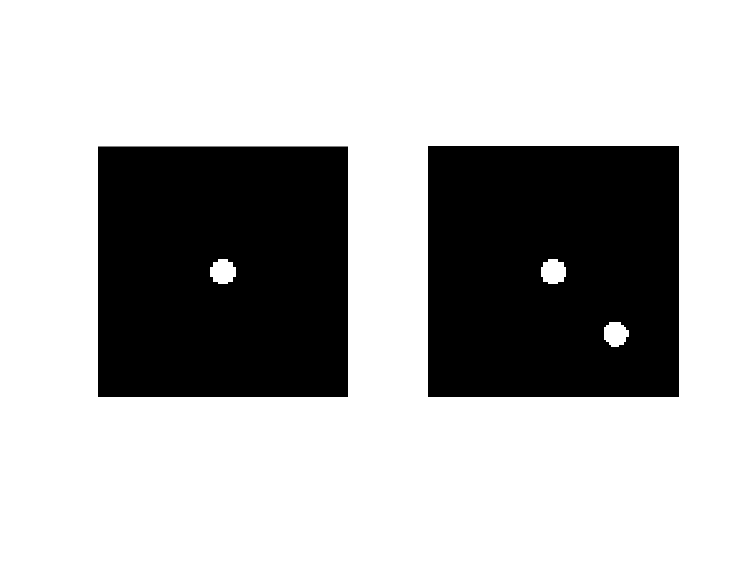

x = linspace(-1,1, 100); y = x;
[X,Y] = meshgrid(x,y);
R = sqrt(X.^2 + Y.^2);
C = zeros(size(X));
C = R < 0.1;

R1 = sqrt((X-0.5).^2 + (Y-0.5).^2);
C1 = zeros(size(X));
C1 = R1 < 0.1;

C2 = C + C1;

figure(1);
subplot(1,2,1);
imshow(C);
subplot(1,2,2);
imshow(C2);

theta = 0:180;
[R,p] = radon(C,theta);